Bewegungsgleichung:

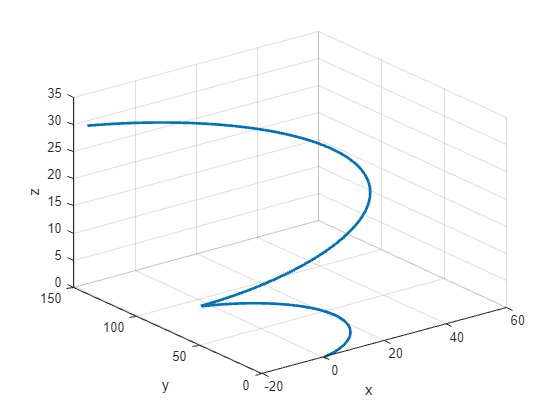

R_0 = [0; 0; 0];
V_0 = [0; 0; 0];
t = linspace(0, 20, 200);
A = [5 * cos(t/2); 5 * sin(t/2); 0.2 * ones(size(t/2))]; % Erhöhte Beschleunigung
V = cumtrapz(t/2, A, 2) + V_0;

R = R_0 + cumtrapz(t/2, V, 2) + 0.5 * cumtrapz(t/2, A, 2) .* t;
figure;
plot3(R(1,:), R(2,:), R(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

Gemessene Werte:

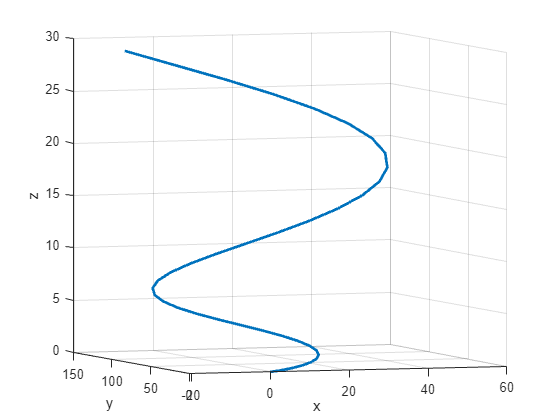

R_measured = extract_every_third_column(R);
figure;
plot3(R_measured(1,:), R_measured(2,:), R_measured(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

% y = awgn(R_measured,5);
% 
% figure;
% plot3(y(1,:), y(2,:), y(3,:), 'LineWidth', 2);
% xlabel('x');
% ylabel('y');
% zlabel('z');
% grid on;


R_measured(3,:)

ans =          0    0.0189    0.0758    0.1705    0.3030    0.4735    0.6818    0.9280    1.2121    1.5341    1.8939    2.2916    2.7272    3.2007    3.7120    4.2613    4.8484    5.4733    6.1362    6.8369    7.5756    8.3521    9.1664   10.0187   10.9088   11.8368   12.8027   13.8065   14.8481   15.9276   17.0450   18.2003   19.3934   20.6245   21.8934   23.2002   24.5448   25.9274   27.3478   28.8061


for i=1:length(R_measured(3,:))
    % Zufällige Werte zwischen -2 und 2 generieren
    randomValues = 4 * rand(1, 1) - 2;
    R_measured(3,i) = R_measured(3,i) + randomValues;
end
R_measured(3,:)

ans =    -0.9008   -1.0151   -0.9517   -1.2129    2.1287    2.2161    1.9567    1.8411   -0.0847    0.9755    0.6491    0.2964    1.9929    3.9991    4.2130    4.4335    4.6045    4.6231    6.1428    7.8831    8.6252    8.6563   10.1571   10.6008    9.4017   11.8544   12.1918   12.1751   13.4395   14.7203   17.7341   17.9263   20.1711   19.6516   19.9324   23.3293   23.6624   27.7123   28.9736   28.3768


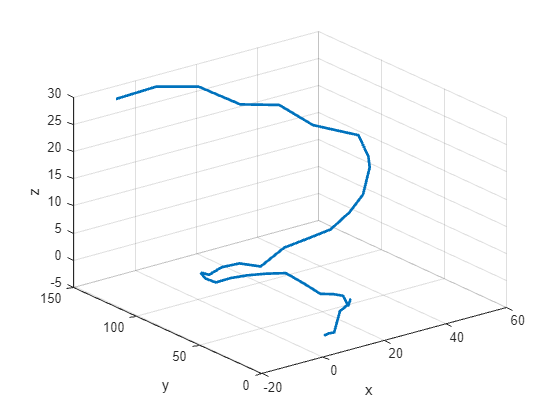

figure;
plot3(R_measured(1,:), R_measured(2,:), R_measured(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

% Gegebene 3D-Punkte (X, Y, Z)
% R_measured = 3x20
points = transpose(R_measured)

points =          0         0   -0.9008
    0.4692    0.0529   -1.0151
    1.8277    0.4155   -0.9517
    3.9327    1.3682   -1.2129
    6.5599    3.1358    2.1287
    9.4238    5.8647    2.2161
   12.2030    9.6079    1.9567
   14.5692   14.3176    1.8411
   16.2176   19.8459   -0.0847
   16.8958   25.9553    0.9755



% Zeitpunkte für die Punkte (optional)
% t = 1x200
t_measured = extract_every_third_column(t)

t_measured =          0    0.5025    1.0050    1.5075    2.0101    2.5126    3.0151    3.5176    4.0201    4.5226    5.0251    5.5276    6.0302    6.5327    7.0352    7.5377    8.0402    8.5427    9.0452    9.5477   10.0503   10.5528   11.0553   11.5578   12.0603   12.5628   13.0653   13.5678   14.0704   14.5729   15.0754   15.5779   16.0804   16.5829   17.0854   17.5879   18.0905   18.5930   19.0955   19.5980


% time = 20x1
time = transpose(t_measured)

time =          0
    0.5025
    1.0050
    1.5075
    2.0101
    2.5126
    3.0151
    3.5176
    4.0201
    4.5226




% Berechnung der Geschwindigkeit
velocityX = diff(points(:, 1)) ./ diff(time);
velocityY = diff(points(:, 2)) ./ diff(time);
velocityZ = diff(points(:, 3)) ./ diff(time);

% Geschwindigkeitsvektor erstellen
% velocityVector = [VX1, VY1, VZ1;
%                   VX2, VY2, VZ2;
%                   VX3, VY3, VZ3;
%                   ...];
velocityVector = [velocityX, velocityY, velocityZ];

% Berechnung der Beschleunigung
accelerationX = diff(velocityVector(:, 1)) ./ diff(time(1:end-1));
accelerationY = diff(velocityVector(:, 2)) ./ diff(time(1:end-1));
accelerationZ = diff(velocityVector(:, 3)) ./ diff(time(1:end-1));

% Beschleunigungsvektor erstellen
accelerationVector = [accelerationX, accelerationY, accelerationZ];


% Ergebnis ausgeben
disp(velocityVector);

    0.9337    0.1052   -0.2275
    2.7035    0.7215    0.1261
    4.1888    1.8961   -0.5199
    5.2281    3.5174    6.6498
    5.6992    5.4304    0.1740
    5.5306    7.4490   -0.5163
    4.7087    9.3723   -0.2301
    3.2803   11.0014   -3.8322
    1.3497   12.1576    2.1098
   -0.9288   12.6975   -0.6497
   -3.3623   12.5270   -0.7018
   -5.7349   11.6109    3.3760
   -7.8250    9.9781    3.9925
   -9.4241    7.7211    0.4257
  -10.3542    4.9914    0.4387
  -10.4842    1.9891    0.3403
   -9.7430   -1.0515    0.0369
   -8.1271   -3.8792    3.0244
   -5.7047   -6.2461    3.4632
   -2.6133   -7.9268    1.4767
    0.9482   -8.7378    0.0619
    4.7322   -8.5539    2.9866
    8.4593   -7.3209    0.8830
   11.8386   -5.0624   -2.3863
   14.5896   -1.8828    4.8809
   16.4640    2.0380    0.6713
   17.2660    6.4537   -0.0332
   16.8697   11.0679    2.5163
   15.2313   15.5533    2.5488
   12.3969   19.5749    5.9975
    8.5025   22.8144    0.3826
    3.7683   24.9941    4.4670
   -1.51

% Ergebnis ausgeben
disp(accelerationVector);

    3.5218    1.2265    0.7037
    2.9559    2.3373   -1.2856
    2.0682    3.2265   14.2676
    0.9374    3.8069  -12.8868
   -0.3356    4.0170   -1.3737
   -1.6355    3.8272    0.5697
   -2.8425    3.2421   -7.1682
   -3.8420    2.3007   11.8245
   -4.5342    1.0743   -5.4914
   -4.8427   -0.3393   -0.1036
   -4.7215   -1.8229    8.1148
   -4.1594   -3.2494    1.2268
   -3.1821   -4.4914   -7.0979
   -1.8508   -5.4321    0.0260
   -0.2588   -5.9746   -0.1958
    1.4751   -6.0507   -0.6038
    3.2156   -5.6273    5.9451
    4.8204   -4.7101    0.8732
    6.1519   -3.3445   -3.9531
    7.0874   -1.6139   -2.8155
    7.5301    0.3658    5.8202
    7.4169    2.4538   -4.1861
    6.7249    4.4943   -6.5059
    5.4745    6.3275   14.4617
    3.7301    7.8023   -8.3771
    1.5960    8.7873   -1.4020
   -0.7888    9.1822    5.0734
   -3.2603    8.9259    0.0648
   -5.6405    8.0030    6.8628
   -7.7499    6.4465  -11.1737
   -9.4210    4.3376    8.1280
  -10.5106    1.8013  -10.9464
  -10.91

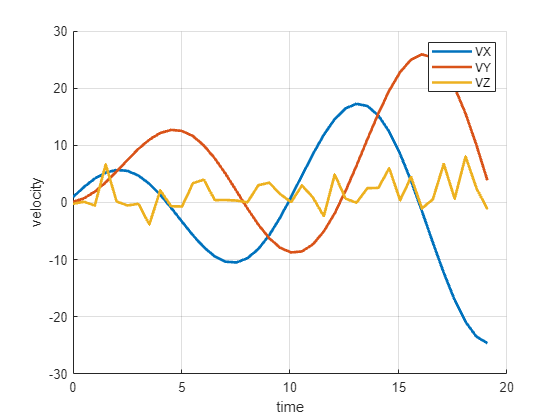

velocityVector = transpose(velocityVector);
time = transpose(time(1:end-1));

figure;
hold on;

plot(time, velocityVector(1,:), 'LineWidth', 2);
plot(time, velocityVector(2,:), 'LineWidth', 2);
plot(time, velocityVector(3,:), 'LineWidth', 2);

xlabel('time');
ylabel('velocity');
grid on;

legend('VX', 'VY', 'VZ');

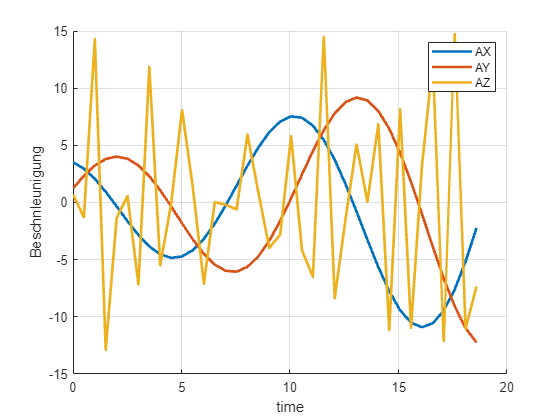

accelerationVector = transpose(accelerationVector);
time = transpose(time(1:end-1));

figure;
hold on;

plot(time, accelerationVector(1,:), 'LineWidth', 2);
plot(time, accelerationVector(2,:), 'LineWidth', 2);
plot(time, accelerationVector(3,:), 'LineWidth', 2);

xlabel('time');
ylabel('Beschnleunigung');
grid on;

legend('AX', 'AY', 'AZ');

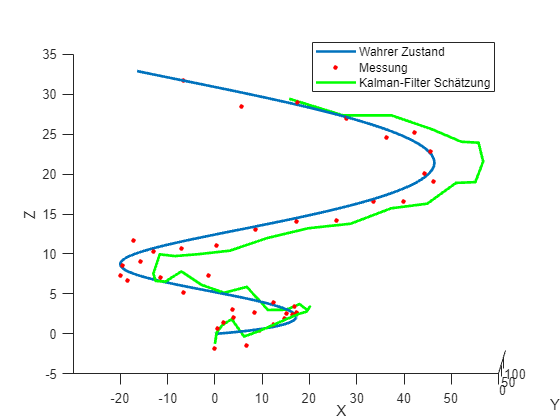

% Gegebenes Beispiel
R_0 = [0; 0; 0];
V_0 = [0; 0; 0];
t = linspace(0, 20, 200);
A = [5 * cos(t/2); 5 * sin(t/2); 0.2 * ones(size(t/2))]; % Erhöhte Beschleunigung
V = cumtrapz(t/2, A, 2) + V_0;

R = R_0 + cumtrapz(t/2, V, 2) + 0.5 * cumtrapz(t/2, A, 2) .* t;

R_measured = extract_every_third_column(R);
for i=1:length(R_measured(3,:))
    % Zufällige Werte zwischen -2 und 2 generieren
    randomValues = 4 * rand(1, 1) - 2;
    R_measured(3,i) = R_measured(3,i) + randomValues;
end

% Kalman-Filter Parameter
dt = 0.5;                % Abtastzeit
A_kalman = [1 dt dt^2/2; 0 1 dt; 0 0 1];       % Zustandsübergangsmatrix
B_kalman = [dt^3/6; dt^2/2; dt];               % Steuerungsmatrix (Beschleunigung)
C_kalman = eye(3);                             % Messmatrix (direkte Messung von X, Y, Z)
Q_kalman = diag([0.8, 0.8, 0.8]);              % Prozessrauschkovarianz
R_kalman = diag([0.3, 0.5, 0.5]);              % Messrauschkovarianz

% Initialisierung
x_kalman = zeros(3, length(R_measured));
P_kalman = zeros(3, 3, length(R_measured));

% Schätzung mit Kalman-Filter
for i = 1:length(R_measured)
    % Vorhersage
    if i == 1
        x_pred = [0; 0; 0];
        P_pred = eye(3);
    else
        x_pred = A_kalman * x_kalman(:, i-1) + B_kalman .* A(:, i-1);
        P_pred = A_kalman * P_kalman(:, :, i-1) * A_kalman' + Q_kalman;
    end
    
    % Korrektur
    K = P_pred * C_kalman' / (C_kalman * P_pred * C_kalman' + R_kalman);
    x_kalman(:, i) = x_pred + K * (R_measured(:, i) - C_kalman * x_pred);
    P_kalman(:, :, i) = (eye(3) - K * C_kalman) * P_pred;
end

% Ergebnisse anzeigen
figure;
hold on;
plot3(R(1,:), R(2,:), R(3,:), 'LineWidth', 2);
plot3(R_measured(1,:), R_measured(2,:), R_measured(3,:), 'r.', 'MarkerSize', 10);
plot3(x_kalman(1,:), x_kalman(2,:), x_kalman(3,:), 'g-', 'LineWidth', 2);
legend('Wahrer Zustand', 'Messung', 'Kalman-Filter Schätzung');
xlabel('X');
ylabel('Y');
zlabel('Z');
view(3);

function new_array = extract_every_third_column(R)
    new_array = R(:, 1:5:end);
end